# Improve Time Resolution

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

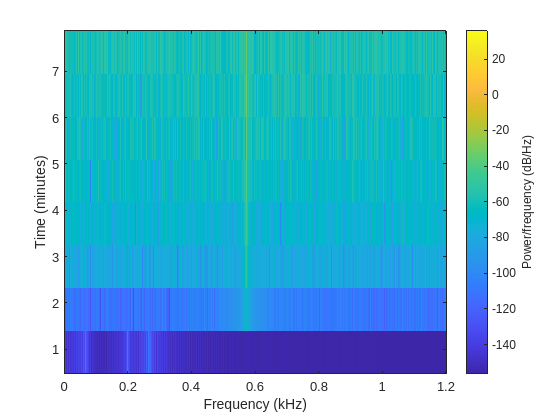

load ./data/monitoredfan.mat 
spectrogram(monitoredfan,[],[],[],fs)

## Task 1

The spectrogram in the live script uses the default settings for the `spectrogram` function, which divides the signal into eight segments. In the first minute, the noise level is very low (around -140 dB). In the second minute, the noise level starts to increase, and the critical frequency locations change. This indicates that the fan broke sometime in the first couple of minutes, but it's not very precise.

This spectrogram is fast to compute because only eight spectra are calculated, but that also means that the spectrogram has a very blocky appearance. In this activity, you'll decrease the window size to improve the time resolution. Unfortunately, this will also decrease the frequency resolution.

w = kaiser(2048,19);

## Task 2

spectrogram(monitoredfan,w,[],[],fs)

## Task 3

The default colormap in MATLAB doesn't have as much contrast as some of the other [available colormaps](https://www.mathworks.com/help/matlab/ref/colormap.html#buc3wsn-6).

`colormap ``map`

colormap jet

## Task 4

Now it is easier to see that there are three tones after the fan broke. The time that the frequencies change is between 2 and 3 minutes. To zoom in on a particular region of the spectrogram, you can use the `xlim` and `ylim` functions.

`ylim``([``t1` `t2``])`

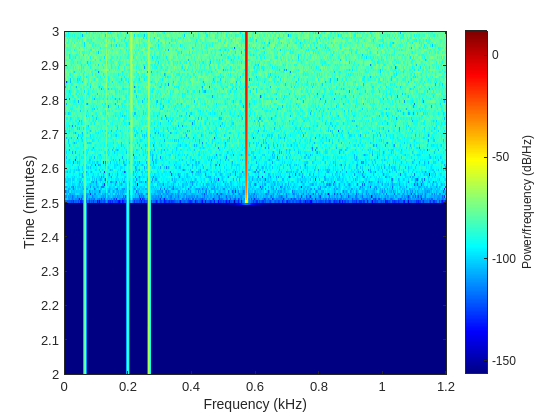

ylim([2 3])